basePath = 'C:\Users\Houssem\Desktop\Sessions UQO\Session Sep 2023\Systèmes de communications multimédias (Nadia)\VisTexColor40_2023\'

basePath = 'C:\Users\Houssem\Desktop\Sessions UQO\Session Sep 2023\Systèmes de communications multimédias (Nadia)\VisTexColor40_2023\'

imgPath = 'C:\Users\Houssem\Desktop\Sessions UQO\Session Sep 2023\Systèmes de communications multimédias (Nadia)\VisTexColor40_2023\Bark.0000.01.tif'

imgPath = 'C:\Users\Houssem\Desktop\Sessions UQO\Session Sep 2023\Systèmes de communications multimédias (Nadia)\VisTexColor40_2023\Bark.0000.01.tif'

nlevels = 3

nlevels = 3

nsubs = 16

nsubs = 16

color = 2

color = 2

[rr,r, rs, ormax,asd] = CBIR_Simple(basePath, nlevels, nsubs,color)

rr =      1     5    16    47     2     2     7    35     6     2    20    53     5    61    54    59     1    19     7   131    63     2   107    11     3    71   146    10    68    35    15   245     1    13    18    23     2    18    31    18     5    19    32    60    13    21     4    17     1     3
     7     1     5    13    14     8     5    14    57     7     6    15    28    89    34    17    15     1     4    11     6    20     8     9    93     9     7    12    35     2     5    25     7     1     2     8     7     3     4     2     6     4     6     8     2     4     2     2     2     1
    22     8     1    16    56    21     3     5    63    21     3    19    30    39     5    28     5     4     1    18    13     4    17     5    28    15    27     6    40     6     2    97    22     3     1    16    23     5     2     5    13    10     7    11     5     5     7     3     7     4
    88    30    34     1   105    83    34     9   188   105    21     2   127   147    36  

r = 76.6504

rs =    38.6719   63.6719   73.0469   74.2188   62.1094   79.2969   78.1250   96.4844   96.4844   60.1562   96.4844   82.4219   94.9219   95.7031   91.7969   98.8281   93.7500   72.2656   94.1406   98.8281   60.5469   49.6094   62.8906   68.7500   87.1094   62.1094   65.2344   64.0625   94.5312   82.8125   83.2031   46.4844   60.9375   63.6719   51.1719   85.1562   99.6094   98.0469   39.0625   99.6094


ormax = 94.8114

asd =     2.7396    3.4076    3.6928    4.3464    2.0647    2.6828    3.7416    4.2015    2.4017    2.8092    4.1394    4.3845    2.6064    3.3457    4.6792    4.4982    4.2158    3.5312    3.2007    2.7177    3.1500    4.1515    2.9530    3.2057    3.6063    2.9947    2.8266    3.0982    3.1810    3.2905    3.4789    2.3437    2.1134    2.2822    2.3228    2.9578    2.0899    2.0104    2.2309    2.2715    2.6135    2.3820    2.5881    2.2034    2.1453    1.9873    1.9037    2.5841    2.8297    2.8535
    2.5068    2.7607    2.9771    2.5454    2.2085    2.6260    2.7305    2.9644    2.1216    2.5732    2.6069    2.6147    2.2959    2.7188    2.5708    2.4116    2.2422    1.8037    1.8853    1.7520    2.3281    2.4922    1.8813    2.0571    2.4487    1.8887    2.0181    2.0146    2.2285    1.9648    2.1250    1.6553    2.7617    2.4888    2.4429    2.8042    2.5454    2.4468    2.5933    2.5352    2.5928    2.5244    2.4766    2.5850    2.5122    2.4624    2.7451    2.6836    3.1592   

imgVector = wavefeat_asd_color(imgPath, nlevels)

imgVector =     2.7396
    2.5068
    2.3958
    1.9297
    1.6984
    0.9526
    1.6505
    0.8778
    1.0385
    0.5565


database_files = dir(fullfile(basePath, '*.tif'))

database_files = 640×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


nimages = length(database_files);

ns= 16;
%Normalisation

%Use standand deviation
%w = std(asd, 1, 2);

%asd= asd./ w(:, ones(1, nimages));


distarray = zeros(nimages,1)

distarray =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


distances =          0    1.0139    2.4899    5.5771    0.8866    0.0488    1.8875    5.6785    0.5933    0.0618    3.5601    6.4500    0.2028    1.8642    8.3240    7.4467    5.8280    4.7514    2.8056    3.2286    3.4358    5.6558    3.2586    2.0057    3.0409    1.6860    4.3368    1.6788    1.4839    4.6858    2.5949    4.4572    2.0574    1.5424    1.6057    0.7177    1.8425    2.0639    1.7703    1.5018    0.8465    1.2008    1.0985    1.4546    1.6903    2.3614    2.9411    1.0229    1.4131    1.2467


sorted_indices =      1     6    10    13   576   573   575     9   287    36   570   286   574   288   283    41     5   274   281   282    51   273   563    82     2   280   568    48    99   566    54   275   276   284   567   277    43    61   616   569    58   572   285   561   611    42   615    50   562    55


top_similar_indices =      1     6    10    13   576   573   575     9   287    36


%distances = sum((asd - imgVector).^2) % Euclidean distance
%[~, sorted_indices] = sort(distances)
%top_similar_indices = sorted_indices(1:min(10, nimages))

for i=1:nimages
	distarray(i) = sum (( abs ( asd (:,i) - imgVector)) .^2, 1);
end

[diff, index] = sort(distarray)

diff =          0
    0.0488
    0.0618
    0.2028
    0.3575
    0.4005
    0.5350
    0.5933
    0.6226
    0.7177


index =      1
     6
    10
    13
   576
   573
   575
     9
   287
    36


Image: Bark.0000.01.tif
Image: Bark.0000.06.tif
Image: Bark.0000.10.tif
Image: Bark.0000.13.tif
Image: Tile.0004.16.tif


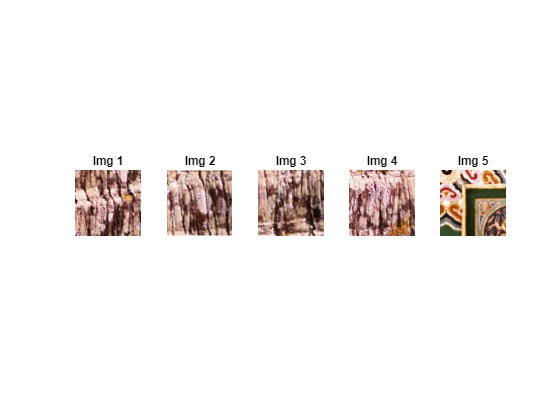

showImages(index,basePath,database_files,5)